% arrange csv files:
% each csv file contains data for one imaging session. The first 4 frames
% are pre-stimulus and frames 5+ are post-stimulus. The first column should
% be time and the 2+ column(s) should be GCaMP signals
ff = uigetdir;
fh = dir(ff);
fh = fh(~[fh(:).isdir]);

traces = nan(65,30);
j = 0;
for i = 1:length(fh)
    data1 = readcsvfiles(strcat(fh(i).folder,'\',fh(i).name));
    traces(1:length(data1),j+1:j+size(data1,2)-1) = data1(:,2:end);
    j = j+size(data1,2)-1;
end
traces = rmmissing(traces,2,"MinNumMissing",30);
traces_sm_pre = sgolayfilt(traces(1:4,:),1,3);
traces_sm_post = sgolayfilt(traces(5:end,:),1,3);
traces_sm = [traces_sm_pre; traces_sm_post];
df = nan(size(traces_sm));
for i = 1:size(traces_sm,2)
    f0 = prctile(traces_sm(1:4,i),10,1);
    df(:,i) = (traces_sm(:,i)-f0)./f0;
end
time = data1(:,1)/1000;
df = rmmissing(df,1,'MinNumMissing',size(df,2));
clear i j data1 f0 ff traces_sm_pre traces_sm_post

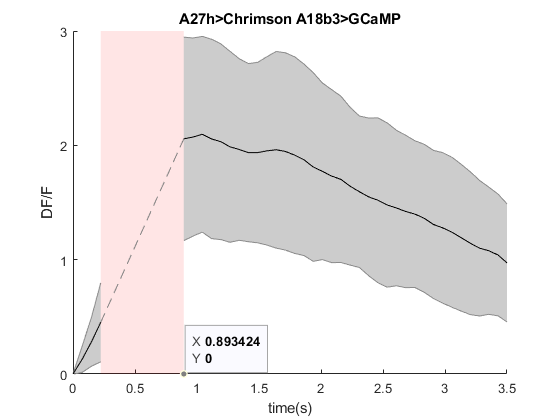

% this will generate the plot for one genotype
prestim = df(1:4,:);
poststim = df(5:end,:);
figure; hold on
shadedErrorBar(time(1:4),mean(prestim,2,"omitnan"),std(prestim,0,2,"omitnan"))
patch([time(4),time(5), time(5), time(4)],[0 0 3 3],'r','facealpha',0.1,'edgecolor','none')
plot([time(4),time(5)],[mean(prestim(end,:)),mean(poststim(1,:))],'--','Color',[0.5 0.5 0.5])
shadedErrorBar(time(5:length(df)),mean(poststim,2,"omitnan"),std(poststim,0,2,"omitnan"))
ylim([0 3])
yticks([0 1 2 3])
xlim([0 3.5])
ylabel('DF/F')
xlabel('time(s)')
title('A27h>Chrimson A18b3>GCaMP')